# *E.coli *(iJO1366) Threonine and Lysine Metabolism

Author: H. Scott Hinton, Utah State University

Reviewer:

## INTRODUCTION

The purpose of this tutorial is to review the basic structure and capabilities of the "Threonine and Lysine Metabolism" subsystem of the iJO1366* E.coli* model.

## MATERIALS

This tutorial is based on the *Constraint-Based Reconstruction and Analysis* (COBRA) Toolbox [1,2]. To use this tutorial requires the 2016a or newer version of Matlab ([https://www.mathworks.com](https://www.mathworks.com)/) and the COBRA toolbox software that can be downloaded from [https://opencobra.github.io/cobratoolbox/latest/index.html.](https://opencobra.github.io/cobratoolbox/latest/index.html.) The installation instructions and troubleshooting tips are also available on this website.

## **EQUIPMENT SETUP**

Initalize the COBRA toolbox.

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  (not installed).
 > Checking if remote can be reached ...  (unsuccessful - no internet connection).
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > Retrieving models ...   Done.


 > Try running
   >> TranslateSBML('C:\Users\hinton\cobratoolbox\test\models\Ec_iAF1260_flux1.xml');
   in order to debug.
 > Configuring solver environment variables ...
   - [----] ILOG_CPLEX_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [-*--] GUROBI_PATH: C:\gurobi702\win64\matlab
   - [----] TOMLAB_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   - [----] MOSEK_PATH :  --> set this path manually after installing the solver ( see <a href="https://opencobra.github.io/cobratoolbox/docs/solvers.html">instructions</a> )
   Done.
 > Checking available solvers and solver interfaces ... Done.
 > Setting default solvers ... Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved in the default location.

 > Summary of available solvers and solver int

Select the optimizer solver.

% changeCobraSolver('glpk','all');
changeCobraSolver('gurobi7','all');

 > CBT_LP_SOLVER has been set to gurobi.
 > CBT_MILP_SOLVER has been set to gurobi.
 > CBT_QP_SOLVER has been set to gurobi.
 > CBT_MIQP_SOLVER has been set to gurobi.
 > CBT_NLP_SOLVER has been set to gurobi.


% changeCobraSolver('tomlab_cplex','all');
% changeCobraSolver('gurobi6','all');

Load the *E.coli *iJO1366 model.

load('iJO1366.mat');
saved_model = iJO1366;
model = saved_model;

## PROCEDURE

## **1.  Threonine and Lysine  Metabolism**

The purpose of this tutorial is to identify and review the structure and capabilities of the "Threonine and Lysine Metabolism" subsystem of the *E.coli* iJO1366 model. This will begin with an overview of the complete subsystem. This overview will be followed by more detailed descriptions of the individaul L-Threonine and L-Lysine biosynthesis pathways. It will conclude with a simulation that shows the maximum flux that each these amino acids can produce in an oxidative range from anaerobic to aerobic conditions.

## **2. "Threonine and Lysine Metabolism" Subsystem**

The reactions associated with the "Threonine and Lysine Metabolism" subsystem can be extracted from the model as shown below.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
ThreonineLysineSubSystems = {'Threonine and Lysine Metabolism'};
ThreonineLysineReactions = model.rxns(ismember(model.subSystems,ThreonineLysineSubSystems));
[tmp,ThreonineLysine_rxnID] = ismember(ThreonineLysineReactions,model.rxns);
reactionNames = model.rxnNames(ThreonineLysine_rxnID);
reactionFormulas = printRxnFormula(model,ThreonineLysineReactions,0);
% T = table(reactionNames,reactionFormulas,'RowNames',ThreonineLysineReactions)
fid = 1;
fprintf(fid,'%-12s %-60s %-50s\r\n','Reaction','Reaction Name','Reaction Formula');

Reaction     Reaction Name                                                Reaction Formula                                  


[nrows,ncols] = size(ThreonineLysineReactions);
for row = 1:nrows
    fprintf(fid,'%-12s %-60s %-50s\r\n',ThreonineLysineReactions{row,:}, reactionNames{row,:}, reactionFormulas{row,:});
end

AOBUTDs      L-2-amino-3-oxobutanoate decarboxylation (spontaneous)       2aobut_c + h_c  -> aact_c + co2_c                 
APPLDHr      Aminopropanol dehydrogenase reversible                       aact_c + h_c + nadh_c  <=> appl_c + nad_c         
ASAD         Aspartate-semialdehyde dehydrogenase                         aspsa_c + nadp_c + pi_c  <=> 4pasp_c + h_c + nadph_c 
ASPK         Aspartate kinase                                             asp__L_c + atp_c  <=> 4pasp_c + adp_c             
ATHRDHr      L-allo-threonine dehydrogenase                               athr__L_c + nadp_c  <=> 2aobut_c + h_c + nadph_c  
DAPDC        Diaminopimelate decarboxylase                                26dap__M_c + h_c  -> co2_c + lys__L_c             
DAPE         Diaminopimelate epimerase                                    26dap_LL_c  <=> 26dap__M_c                        
DHDPRy       Dihydrodipicolinate reductase (NADPH)                        23dhdp_c + h_c + nadph_c  -> nadp_c + thdp_c    

**Table 1**. Reaction names and formulas for members of the "Threonine and Lysine Metabolism" Subsystem.

The connectivity between these reactions can be visualized through an Escher [3] map of this  "Threonine and Lysine Metabolism" subsystem as shown below (Threonine_Asprartate_Metaboism_Subsystem.json).

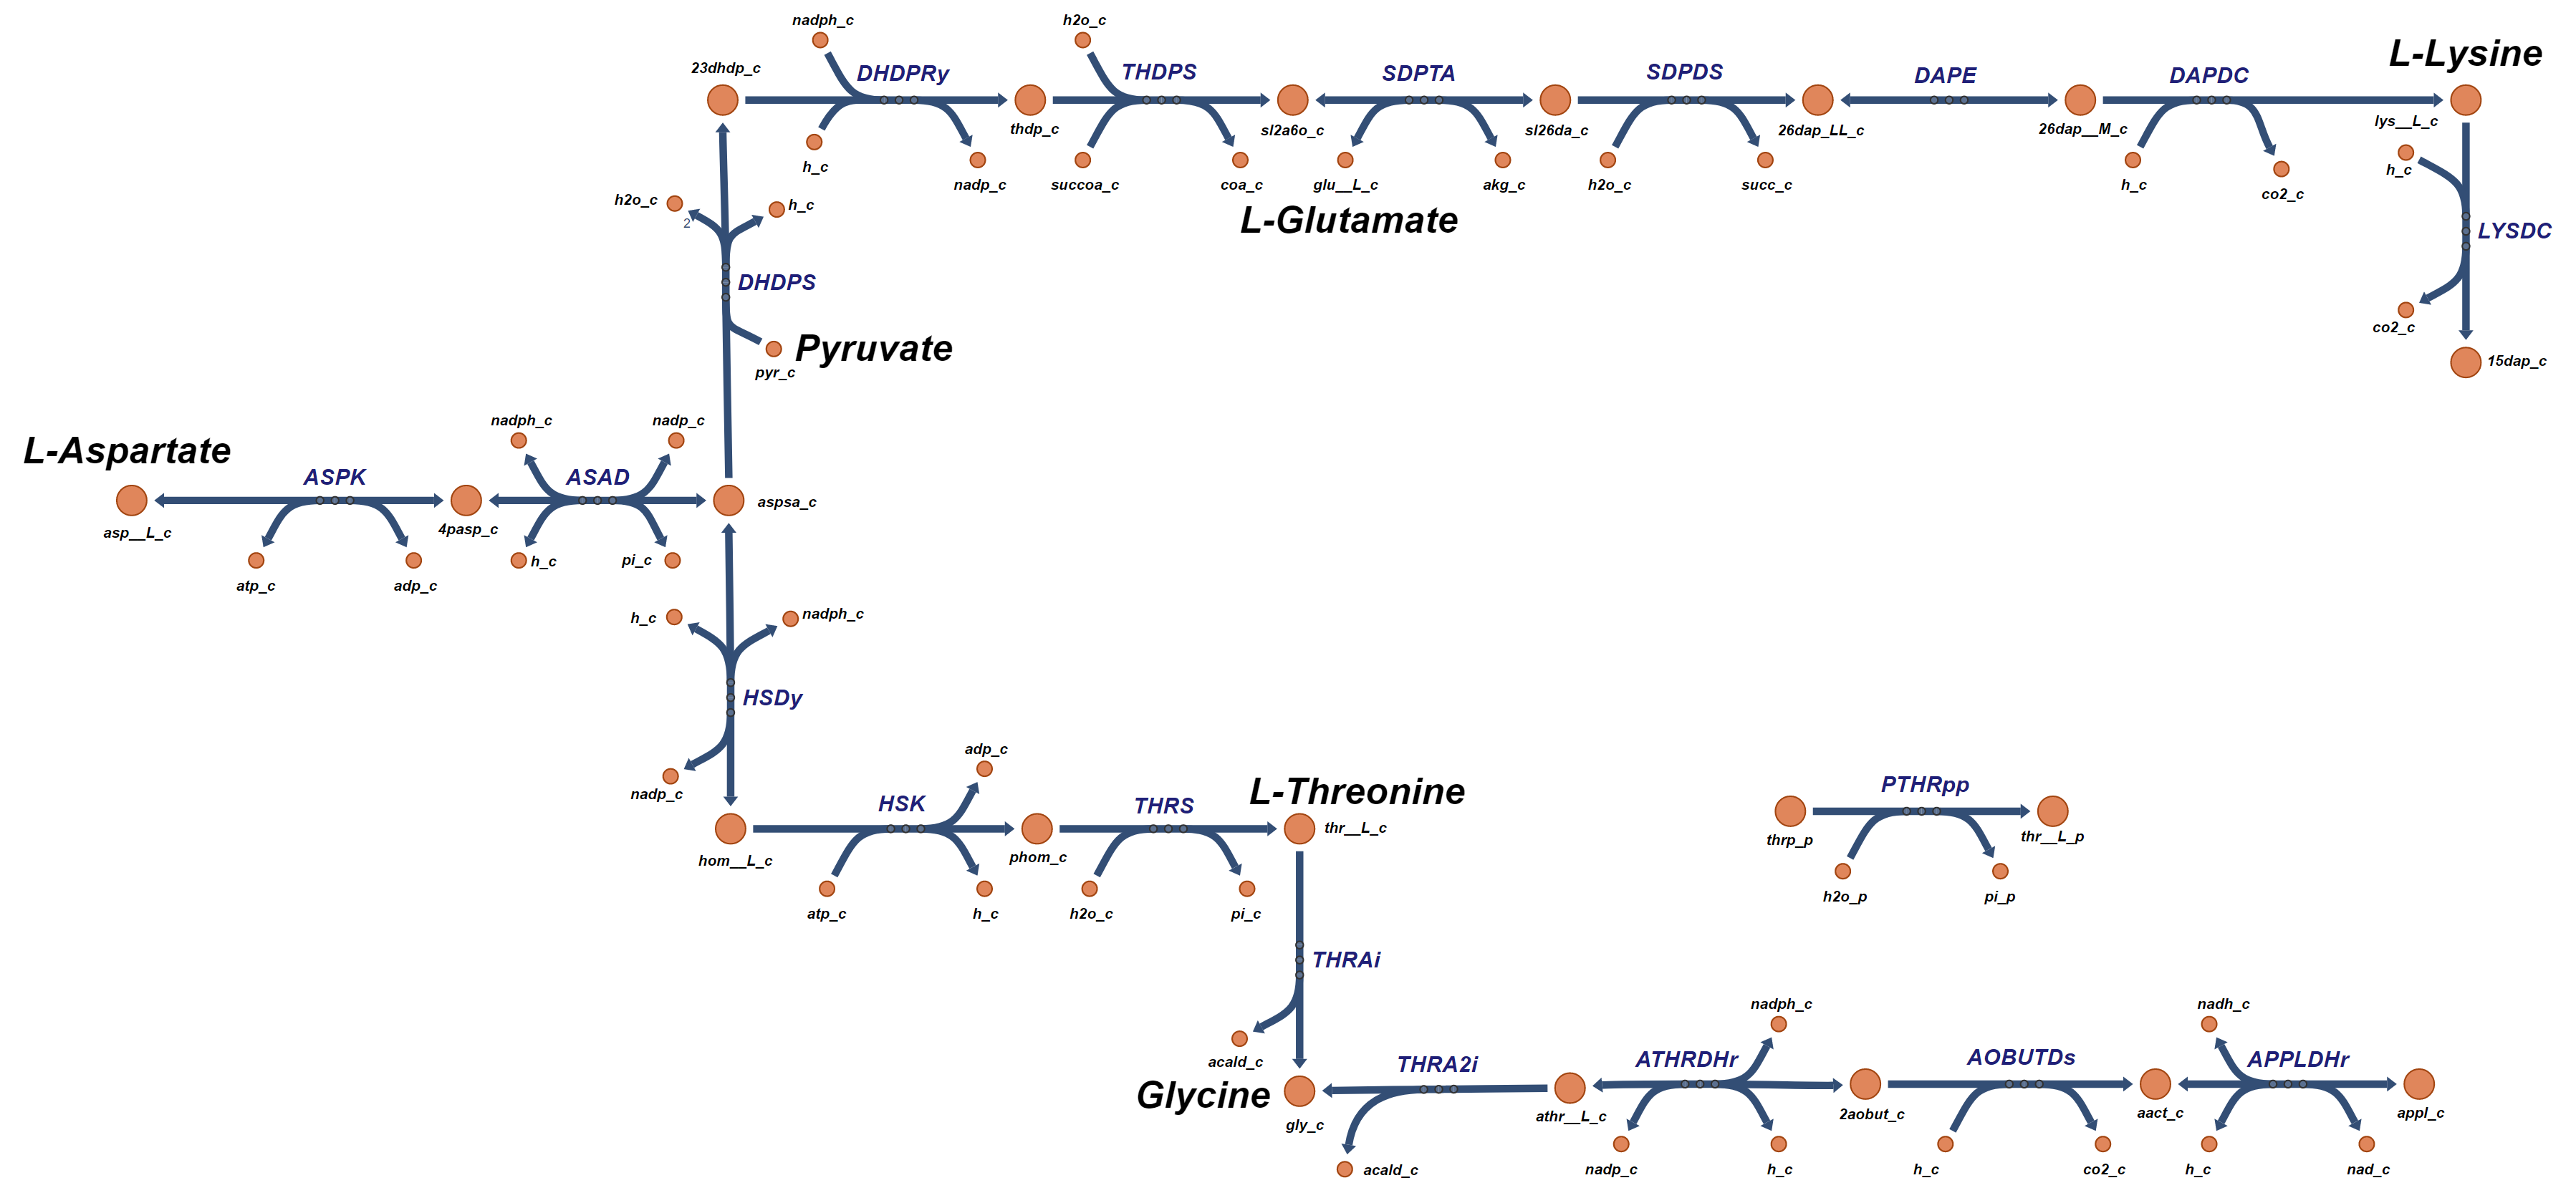

**Figure 1.** The reactions and pathways associated with the "Threonine and Lysine Metabolism" subsystem.

The  "Threonine and Lysine Metabolism" subsystem includes the primary biosynthesis pathways for both L-Therionine and L-Lysine. Both of these pathways begin with L-Aspartate and pass through two common reactions; 'ASPK' and 'ASAD'. The pathway to L-Lysine involves seven additional reactions ('DHDPS', 'DHDPRy', 'THDPS', 'SDPTA', 'SDPDS', 'DAPE', and 'DAPDC') while the pathway to L-Threonine on requires three addtiiona reactions ('HSDy', 'HSK', and 'THRS'). There is one L-Lysine consuming reaction included in this subsytem, 'LYSDC'. There is also one L-Threonine consuming reaction included in this subsytem, 'THRAi', that produces Glycine. For some reason, these is also a partial pathway that can lead to the biosynthesis of Glycine from the beginning metabolite of 1-Aminopropan-2-ol. Finally there is a reaction ('PTHRpp') that converts periplasmic L-Threonine O-3-phosphate ('thrp_p') to periplamic L-Threonine ('thr__L_p').

Now let's begin exploring the biosynthesis pathways for L-Threonine and L-Lysine.

## **3. L-Threonine Biosynthesis**

The chemical structure for L-Threonine (${\mathrm{C}}_4 {\mathrm{H}}_9 {\text{NO}}_3$) is shown below. 

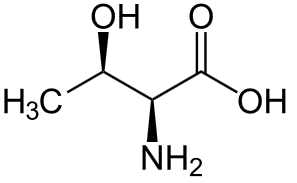

**Figure 2**. The chemical structure of L-Threonine (${\mathrm{C}}_4 {\mathrm{H}}_9 {\text{NO}}_3$) - Wikipedia

## 3.1. L-Threonine Biosynthesis Pathways

According to the "Threonine and Lysine Metabolism" subsystem there is only one pathway to produce L-Threonine, it includes the following reactions 'ASPK', 'ASAD', 'HSDy', 'HSK', and 'THRS'. The individual reactions that both consume and produce L-Threonine can be calculated with the COBRA Tollbox function "surfNet".

surfNet(model, 'thr__L_c')


Met #942  thr__L_c, L-Threonine, C4H9NO3
Consuming reactions:
#7  BIOMASS_Ec_iJO1366_WT_53p95M  E. coli biomass objective function (iJO1366) - WT - with 53.95 GAM estimate  
  0.000223 10fthf_c + 0.000223 2dmmql8_c + 2.5e-05 2fe2s_c + 
  0.000248 4fe4s_c + 0.000223 5mthf_c + 0.000279 accoa_c + 0.000223 adocbl_c 
  + 0.49915 ala__L_c + 0.000223 

From these results we can see that there are four major pathways leading to the production of L-Threonine. The first pathway is the primary pathway that ends with 'THRS'. The other three pathways ('THRabcpp', 'THRt2rpp', and 'THRt4pp') are associated with transport pathways that bring diffused L-Threonine from the periplasmic space. 

We using the Escher tool [3] can now build a represenation of all the reactions and pathways that can lead to the biosynthesis of L-Threonine.

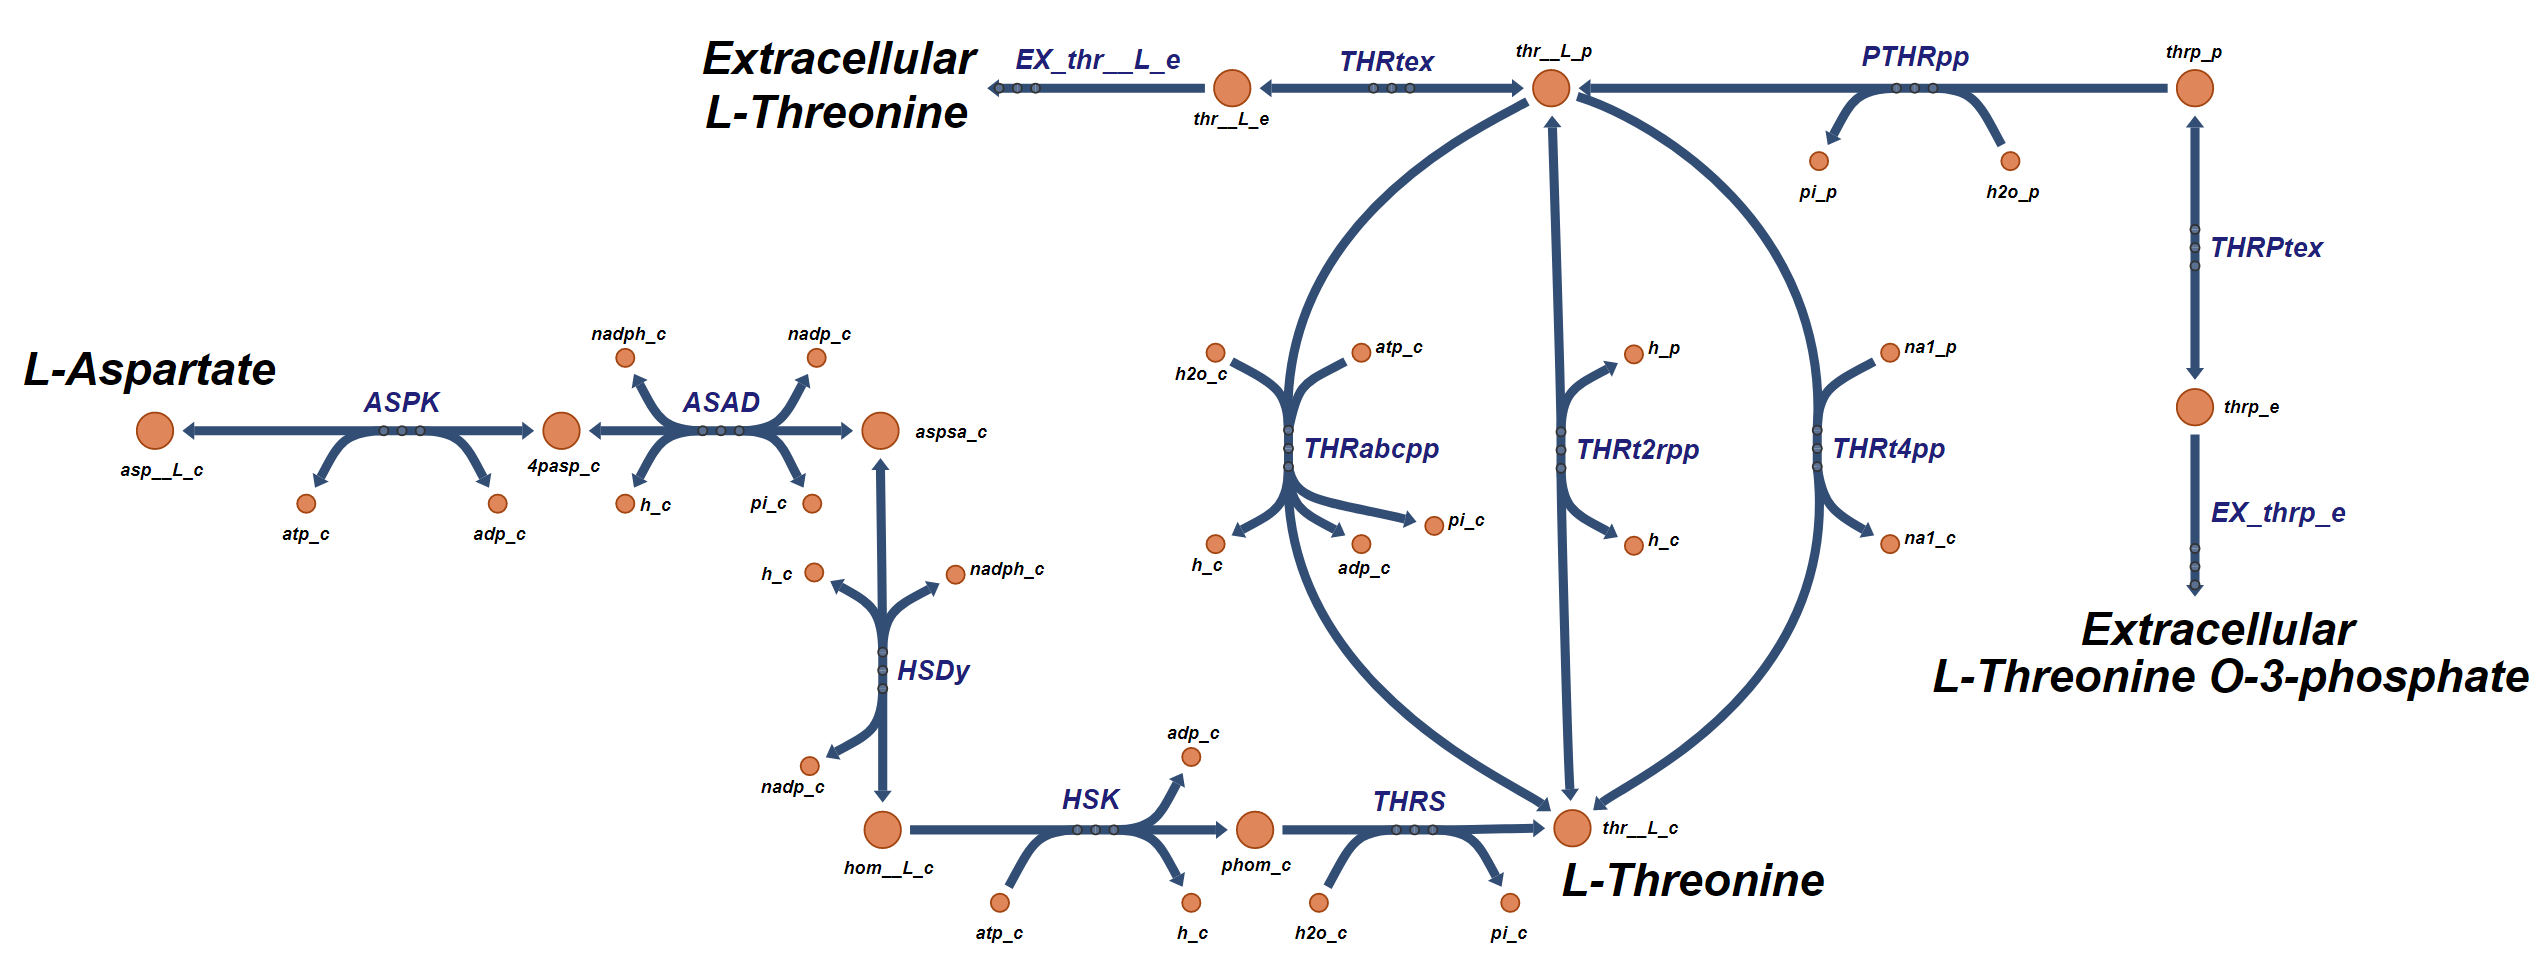

**Figure 3.** Biosynthesis pathways for the production of L-Threonine (Threonine_Biosynthesis.json, Threonine_Biosynthesis.png or Threonine_Biosynthesis.svg).

There are four major pathways leading to the production of L-Threonine. The first pathway is the primary pathway that includes; 'ASPK', 'ASAD', 'HSDy', 'HSK', and 'THRS'. The other three pathways ('THRabcpp', 'THRt2rpp', and 'THRt4pp') are associated with transport pathways that bring diffused L-Threonine from the periplasmic space. The pathway that models the diffusion of extracellular L-Threonine into the periplasm includes the reactions 'EX_thr__L_e' and 'THRtex'. Another pathway that leads to periplasmic L-Threonine ('thr__L_p') begins with extracellular L-Threonine O-3-phosphate and includes the following reactions; 'EX_thrp_e', 'THRPtex' and 'PTHRpp'.

The formulas for these L-Threonine producing reactions can be found as shown below.

model = saved_model;
ThreonineBiosynthesisReactions = transpose({'ASPK','ASAD','HSDy','HSK','THRS','THRabcpp','THRt2rpp','THRt4pp',...
    'EX_thr__L_e','THRtex','EX_thrp_e', 'THRPtex','PTHRpp'});
[tmp,ThreonineBiosynthesis_rxnID] = ismember(ThreonineBiosynthesisReactions,model.rxns);
reactionNames = model.rxnNames(ThreonineBiosynthesis_rxnID);
reactionFormulas = printRxnFormula(model,ThreonineBiosynthesisReactions,0);
% T = table(reactionNames,reactionFormulas,'RowNames',MethionineBiosynthesisReactions)
fid = 1;
fprintf(fid,'%-15s %-75s %-50s\r\n','Reaction','Reaction Name','Reaction Formula');

Reaction        Reaction Name                                                               Reaction Formula                                  


[nrows,ncols] = size(ThreonineBiosynthesisReactions);
for row = 1:nrows
    fprintf(fid,'%-15s %-75s %-50s\r\n',ThreonineBiosynthesisReactions{row,:}, reactionNames{row,:}, reactionFormulas{row,:});
end

ASPK            Aspartate kinase                                                            asp__L_c + atp_c  <=> 4pasp_c + adp_c             
ASAD            Aspartate-semialdehyde dehydrogenase                                        aspsa_c + nadp_c + pi_c  <=> 4pasp_c + h_c + nadph_c 
HSDy            Homoserine dehydrogenase (NADPH)                                            hom__L_c + nadp_c  <=> aspsa_c + h_c + nadph_c    
HSK             Homoserine kinase                                                           atp_c + hom__L_c  -> adp_c + h_c + phom_c         
THRS            Threonine synthase                                                          h2o_c + phom_c  -> pi_c + thr__L_c                
THRabcpp        L-threonine transport via ABC system (periplasm)                            atp_c + h2o_c + thr__L_p  -> adp_c + h_c + pi_c + thr__L_c 
THRt2rpp        L-threonine reversible transport via proton symport (periplasm)             h_p + thr__L_p  <=> h_c + thr__L_c    

**Table 2. **Reactions names and formulas for L-Threonine biosynthesis reactions.

We can also find the subsystems that are associated with each of these reactions.

reactionSubsystems = model.subSystems(ThreonineBiosynthesis_rxnID);
% T = table(reactionNames,reactionSubsystems,'RowNames',MethionineBiosynthesisReactions)
fid = 1;
fprintf(fid,'%-15s %-75s %-50s\r\n','Reaction','Reaction Name','Reaction Subsystem');

Reaction        Reaction Name                                                               Reaction Subsystem                                


[nrows,ncols] = size(ThreonineBiosynthesisReactions);
for row = 1:nrows
    fprintf(fid,'%-15s %-75s %-50s\r\n',ThreonineBiosynthesisReactions{row,:}, reactionNames{row,:}, reactionSubsystems{row,:});
end

ASPK            Aspartate kinase                                                            Threonine and Lysine Metabolism                   
ASAD            Aspartate-semialdehyde dehydrogenase                                        Threonine and Lysine Metabolism                   
HSDy            Homoserine dehydrogenase (NADPH)                                            Threonine and Lysine Metabolism                   
HSK             Homoserine kinase                                                           Threonine and Lysine Metabolism                   
THRS            Threonine synthase                                                          Threonine and Lysine Metabolism                   
THRabcpp        L-threonine transport via ABC system (periplasm)                            Transport, Inner Membrane                         
THRt2rpp        L-threonine reversible transport via proton symport (periplasm)             Transport, Inner Membrane                         

**Table 3. **Reactions names and subsystems for L-Threonine biosynthesis reactions.

## 3.2 L-Threonine Aerobic Operation

The fluxes for these L-Threonine producing reactions, under aerobic conditions, can be extracted from the iJO1366 model as follows.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
printLabeledData(ThreonineBiosynthesisReactions, round(FBAsolution.x(ThreonineBiosynthesis_rxnID),3))

ASPK	1.05	
ASAD	-1.05	
HSDy	-0.686	
HSK	0.535	
THRS	0.535	
THRabcpp	0	
THRt2rpp	0	
THRt4pp	0	
EX_thr__L_e	0	
THRtex	0	
EX_thrp_e	0	
THRPtex	0	
PTHRpp	0	


This can be seen using an Escher [3] plot with the "Aerobic_Reaction_Flux.csv" data.

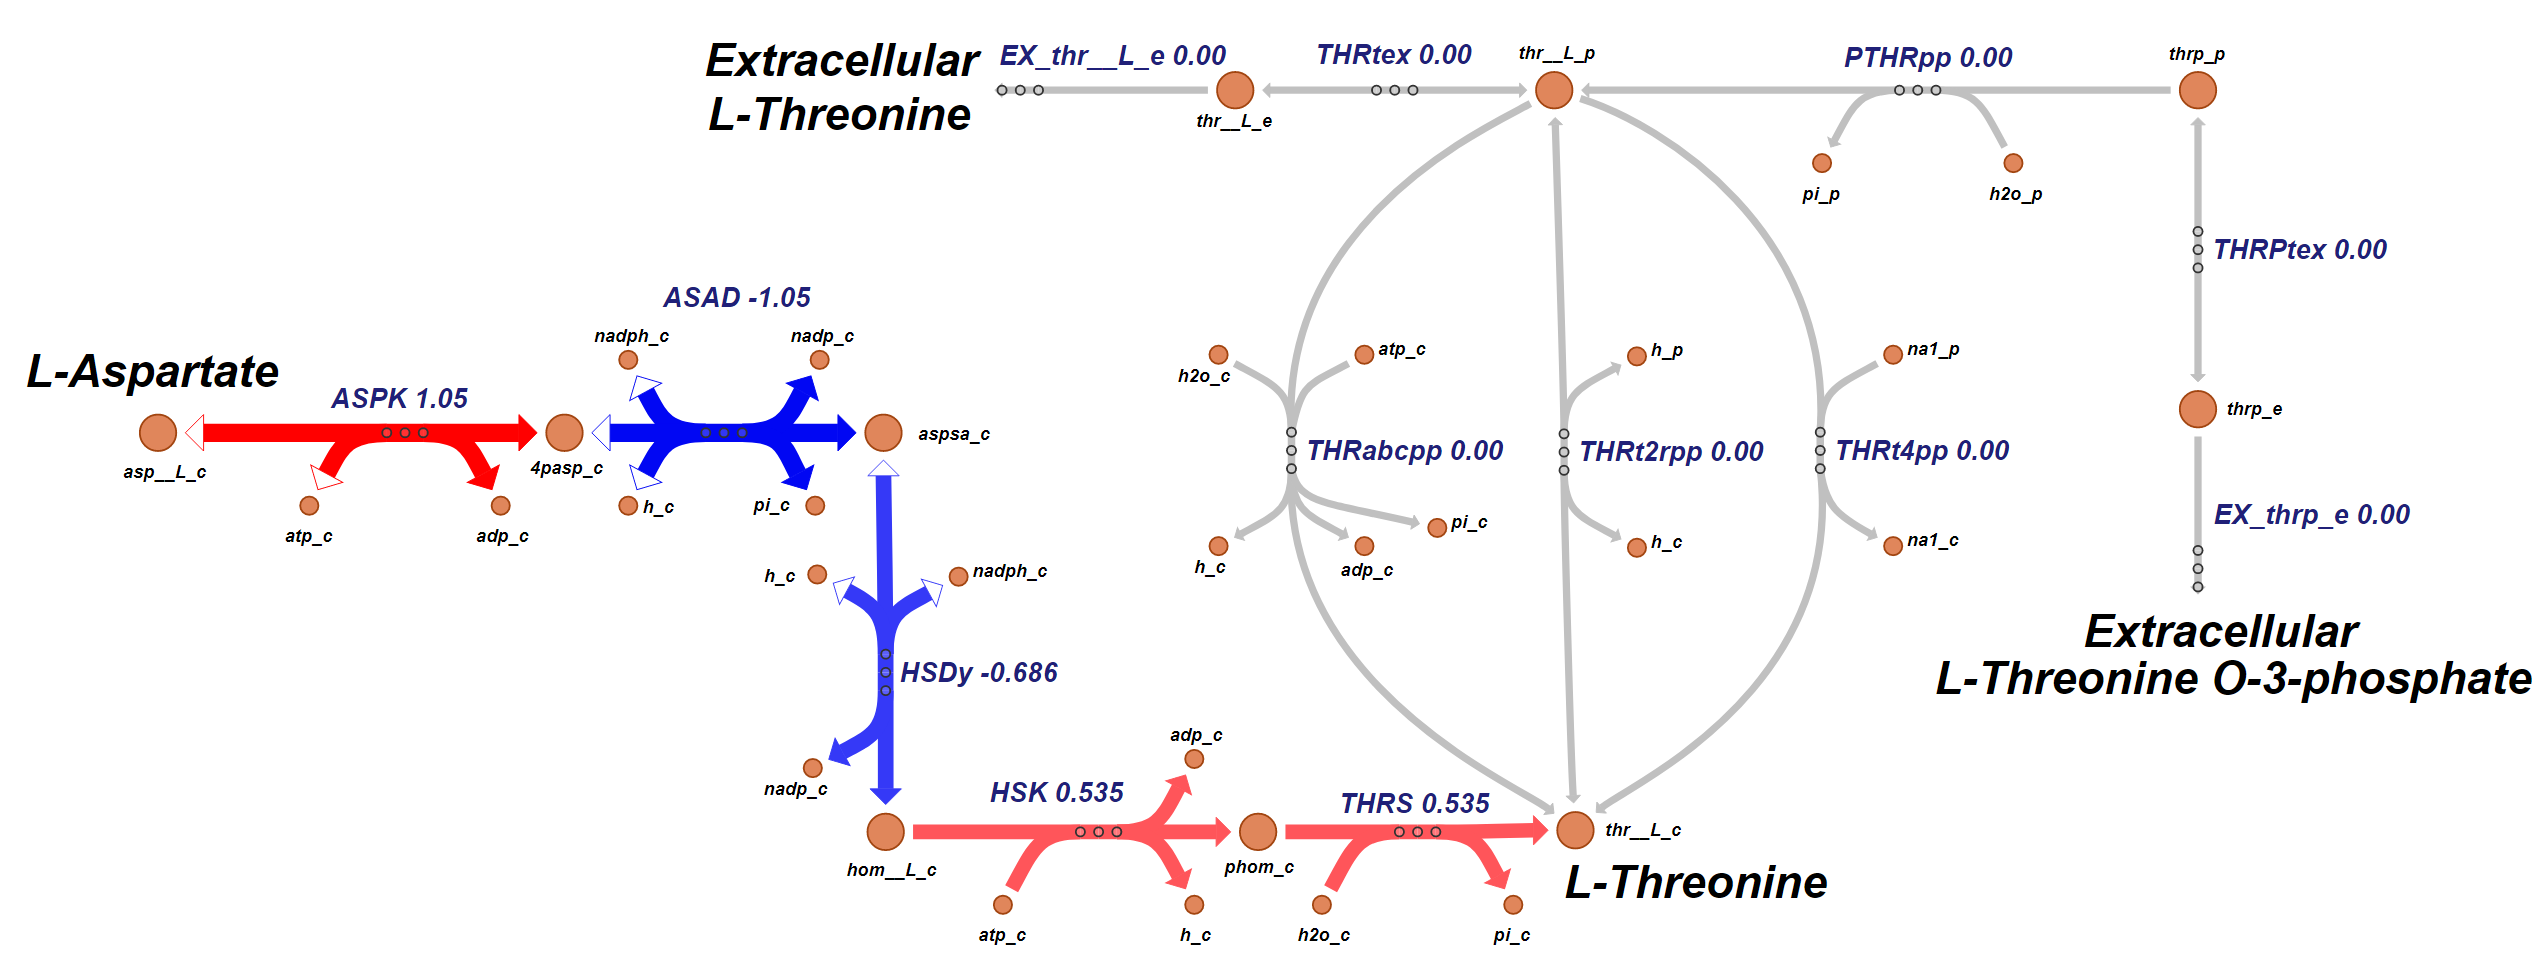

**Figure 4.** L-Threonine production under aerobic conditions (Threonine_Biosynthesis_Aerobic.png or Threonine_Biosynthesis_Aerobic.svg).

This figure illustrates that only the primary biosynthesis pathway is used in this simple aerobic case. Note that both reactions 'ASAD' and 'HSDy' are reactions operating in reverse mode. For this figure red indicates the reaction is operating in the forward mode of operation with the thicknes of the line associated with the amount of flux. The blue indicates the reaction is operating in the reverse mode of operation.

## 3.3 Excess L-Threonine Production

When a cell is producing a recombinant protein, it might be required to produce additional L-Threonine for the desired bioproduct.  What is the maximum amount of excess L-Threonine, beyond what the cell needs for normal growth, that can be produced for a given growth-rate?

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',FBAsolution.f,'b'); % Set fixed growth-rate
model = addDemandReaction(model, 'thr__L_c');

DM_thr__L_c	thr__L_c 	->	


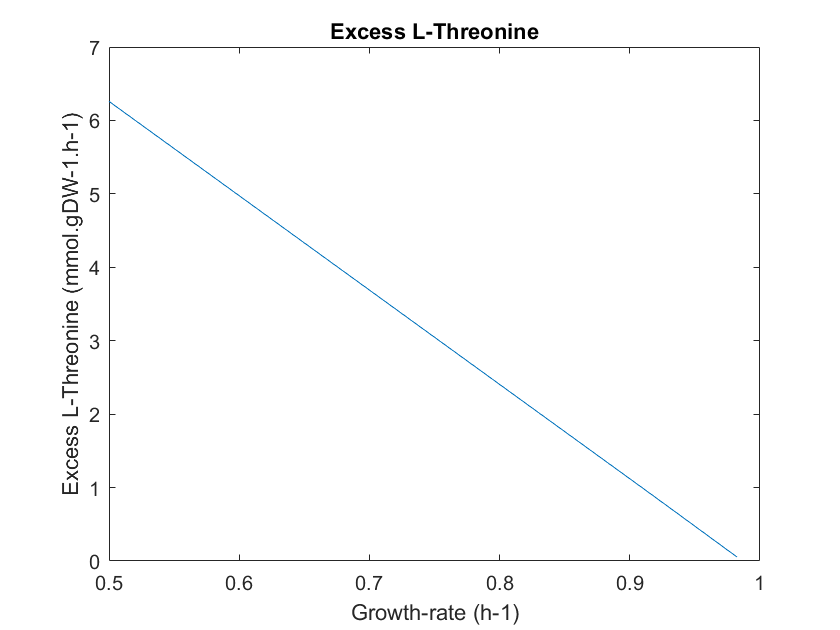

[tmp,Threonine_MAX_rxnID] = ismember({'DM_thr__L_c'},model.rxns);
model = changeObjective(model,'DM_thr__L_c'); % Set the objective function
FBAsolution_Threonine = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
xMin = 0.5;
xMax = FBAsolution.f;
xInc = (xMax - xMin)/20;
x = xMin;
excessThreonine = [];
growthRate = [];
for i = 1:21
    model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',x,'b'); % Set fixed growth-rate  
    FBAsolution_Threonine = optimizeCbModel(model,'max'); % Perform FBA
    excessThreonine(i) = FBAsolution_Threonine.f;
    growthRate(i) = x;
    x = x + xInc;
end
plot(growthRate,excessThreonine)
title('Excess L-Threonine'); 
xlabel('Growth-rate (h-1)'); ylabel('Excess L-Threonine (mmol.gDW-1.h-1)');

**Figure 5. **A plot showing the maximum amount of L-Threonine that can be produced for a given growth-rate.

This figure illustrates that as the need for excess L-Threonine increases the growth-rate will need to decrease. In this figure we can see that the excess L-Threonine flux can increase from 0.05376 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when the cell is at maximum growth-rate to 6.259 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when it is at 50% of that optimal growth-rate. Finally, to increase the L-Threonine flux beyond these levels will require using the pathways that allow for the transport of L-Threonine from the extracellular media. 

## **4. L-Lysine Biosynthesis**

The chemical structure for L-Lysine (${\mathrm{C}}_6 {\mathrm{H}}_{14} {\mathrm{N}}_2 {\mathrm{O}}_2$) is shown below. 

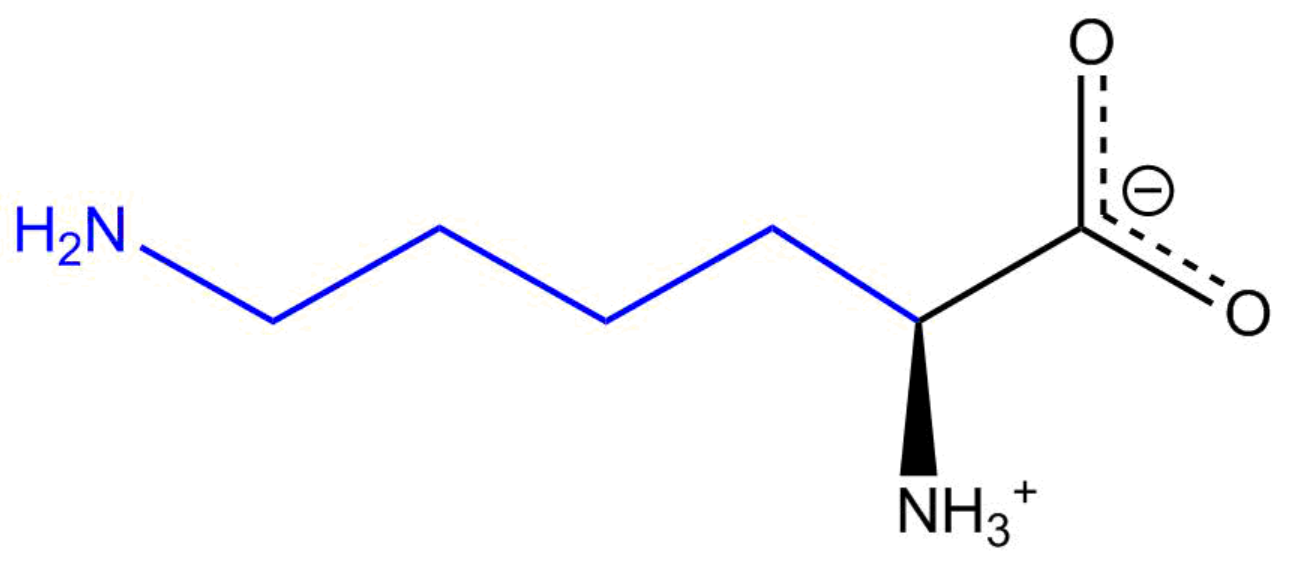

**Figure 6**. The chemical structure of L-Lysine(${\mathrm{C}}_6 {\mathrm{H}}_{14} {\mathrm{N}}_2 {\mathrm{O}}_2$) - Wikipedia

## 4.1.  **L-Lysine** Biosynthesis Pathways

According to the "Threonine and Lysine Metabolism" subsystem there is only one pathway to produce L-Lysine, it includes the following reactions 'ASPK', 'ASAD', 'DHDPS', 'DHDPRy', 'THDPS', 'SDPTA', 'SDPDS', 'DAPE', and 'DAPDC'. The individual reactions that both consume and produce L-Lysine can be calculated with the COBRA Tollbox function "surfNet".

surfNet(model, 'lys__L_c')


Met #661  lys__L_c, L-Lysine, C6H15N2O2
Consuming reactions:
#7  BIOMASS_Ec_iJO1366_WT_53p95M  E. coli biomass objective function (iJO1366) - WT - with 53.95 GAM estimate  
  0.000223 10fthf_c + 0.000223 2dmmql8_c + 2.5e-05 2fe2s_c + 
  0.000248 4fe4s_c + 0.000223 5mthf_c + 0.000279 accoa_c + 0.000223 adocbl_c 
  + 0.49915 ala__L_c + 0.000223 

From these results we can see that there are five reactions that produce cytoplasmic L-Lysine in the direction, they include  'CADVtpp', 'DAPDC', 'FRULYSDG', 'LYSabcpp' and 'LYSt2pp'. There are aslo no birectional reactions listed under the consuming reactions. 

We using the Escher tool [3] can now build a represenation of all the reactions and pathways that can lead to the biosynthesis of L-Lysine.

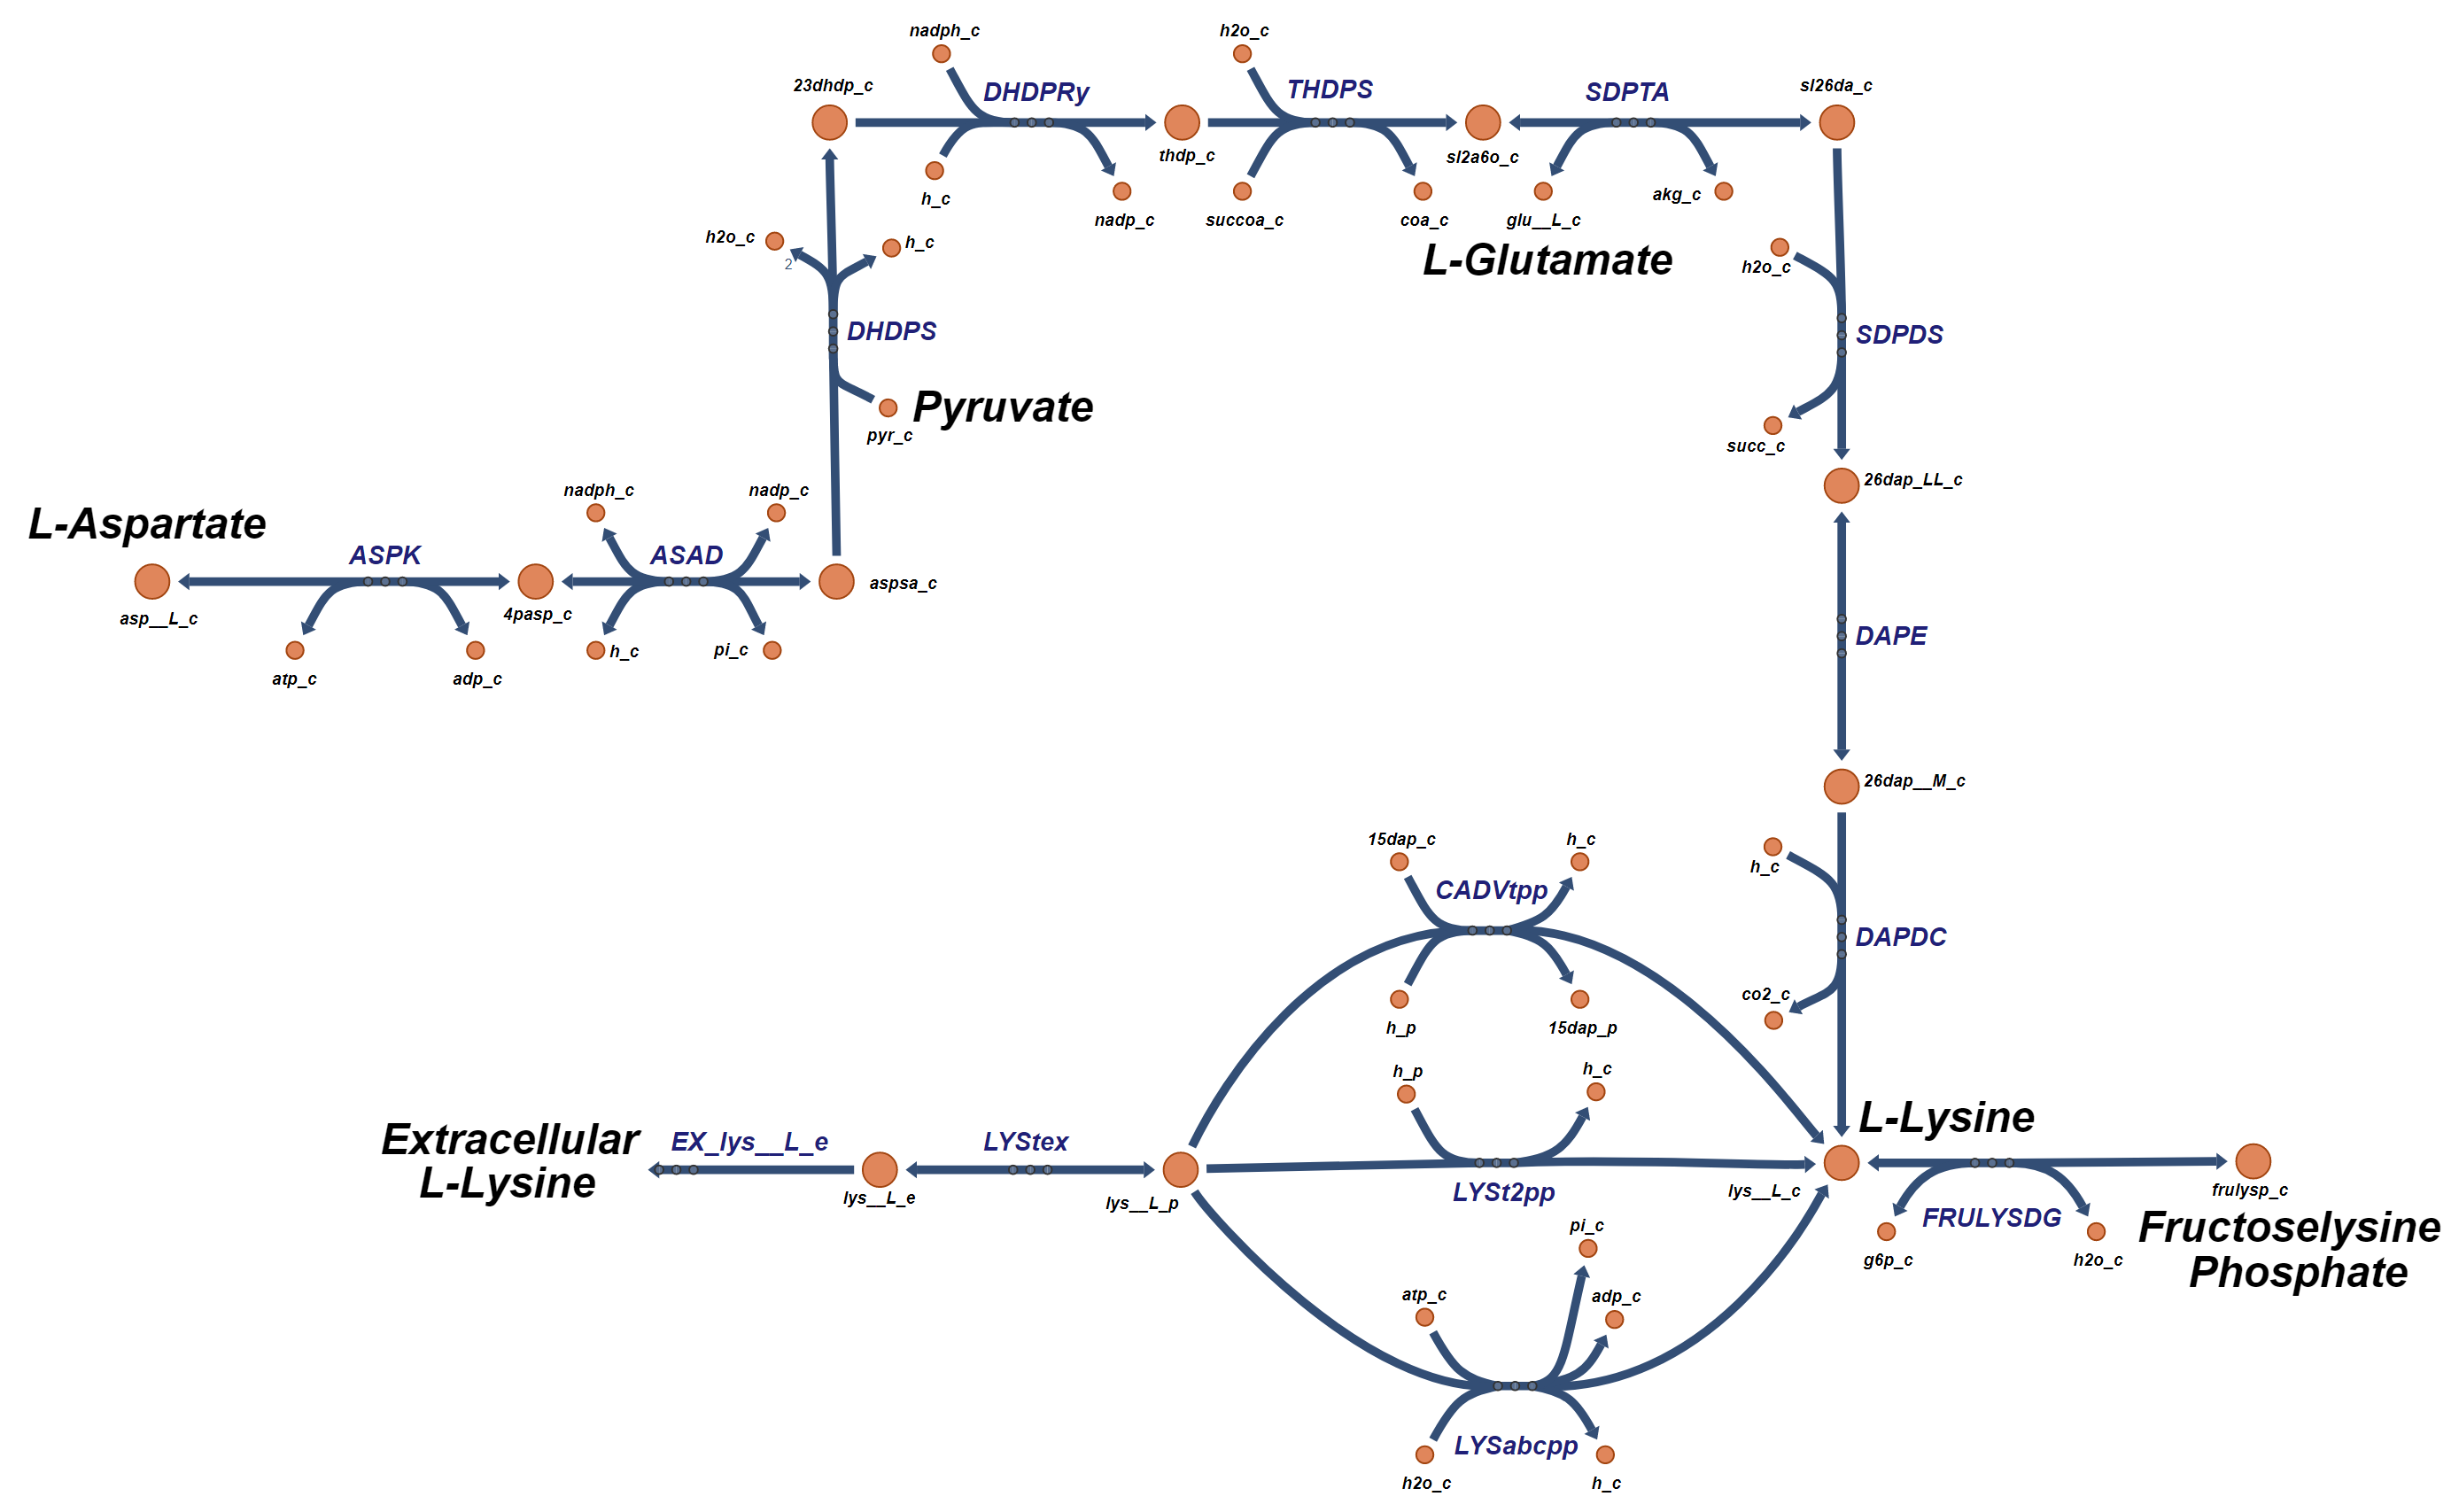

**Figure 7. **Biosynthesis pathways for the production of L-Lysine (Lysine_Biosynthesis.json, Lysine_Biosynthesis.png or Lysine_Biosynthesis.svg).

There are five major pathways leading to the production of L-Lysine. The first pathway is the primary pathway that includes; 'ASPK', 'ASAD', 'DHDPS', 'DHDPRy', 'THDPS', 'SDPTA', 'SDPDS', 'DAPE', and 'DAPDC'. The other three pathways ('CADVtpp', 'LYSt2pp', and 'LYSabcpp') are associated with transport pathways that bring diffused L-Lysine from the periplasmic space. The pathway that models the diffusion of extracellular L-Lysine into the periplasm includes the reactions 'EX_lys__L_e' and 'LYStex'. Finally, another reaction that leads to the production of L-Lysine is 'FRULYSDG' which converts the internal metabolite Fructoselysine phosphate ('frulysp_c') to L-Lysine.

The formulas for these L-Lysine producing reactions can be found as shown below.

model = saved_model;
LysineBiosynthesisReactions = transpose({'ASPK', 'ASAD', 'DHDPS', 'DHDPRy', 'THDPS', 'SDPTA', 'SDPDS', 'DAPE','DAPDC',...
    'CADVtpp', 'LYSt2pp','LYSabcpp','EX_lys__L_e','LYStex','FRULYSDG'});
[tmp,LysineBiosynthesis_rxnID] = ismember(LysineBiosynthesisReactions,model.rxns);
reactionNames = model.rxnNames(LysineBiosynthesis_rxnID);
reactionFormulas = printRxnFormula(model,LysineBiosynthesisReactions,0);
% T = table(reactionNames,reactionFormulas,'RowNames',MethionineBiosynthesisReactions)
fid = 1;
fprintf(fid,'%-15s %-65s %-50s\r\n','Reaction','Reaction Name','Reaction Formula');

Reaction        Reaction Name                                                     Reaction Formula                                  


[nrows,ncols] = size(LysineBiosynthesisReactions);
for row = 1:nrows
    fprintf(fid,'%-15s %-65s %-50s\r\n',LysineBiosynthesisReactions{row,:}, reactionNames{row,:}, reactionFormulas{row,:});
end

ASPK            Aspartate kinase                                                  asp__L_c + atp_c  <=> 4pasp_c + adp_c             
ASAD            Aspartate-semialdehyde dehydrogenase                              aspsa_c + nadp_c + pi_c  <=> 4pasp_c + h_c + nadph_c 
DHDPS           Dihydrodipicolinate synthase                                      aspsa_c + pyr_c  -> 23dhdp_c + h_c + 2 h2o_c      
DHDPRy          Dihydrodipicolinate reductase (NADPH)                             23dhdp_c + h_c + nadph_c  -> nadp_c + thdp_c      
THDPS           Tetrahydrodipicolinate succinylase                                h2o_c + succoa_c + thdp_c  -> coa_c + sl2a6o_c    
SDPTA           Succinyldiaminopimelate transaminase                              akg_c + sl26da_c  <=> glu__L_c + sl2a6o_c         
SDPDS           Succinyl-diaminopimelate desuccinylase                            h2o_c + sl26da_c  -> 26dap_LL_c + succ_c          
DAPE            Diaminopimelate epimerase                         

**Table 4. **Reactions names and formulas for L-Lysine biosynthesis reactions.

We can also find the subsystems that are associated with each of these reactions.

reactionSubsystems = model.subSystems(LysineBiosynthesis_rxnID);
% T = table(reactionNames,reactionSubsystems,'RowNames',LysineBiosynthesisReactions)
fid = 1;
fprintf(fid,'%-15s %-65s %-50s\r\n','Reaction','Reaction Name','Reaction Subsystem');

Reaction        Reaction Name                                                     Reaction Subsystem                                


[nrows,ncols] = size(LysineBiosynthesisReactions);
for row = 1:nrows
    fprintf(fid,'%-15s %-65s %-50s\r\n',LysineBiosynthesisReactions{row,:}, reactionNames{row,:}, reactionSubsystems{row,:});
end

ASPK            Aspartate kinase                                                  Threonine and Lysine Metabolism                   
ASAD            Aspartate-semialdehyde dehydrogenase                              Threonine and Lysine Metabolism                   
DHDPS           Dihydrodipicolinate synthase                                      Threonine and Lysine Metabolism                   
DHDPRy          Dihydrodipicolinate reductase (NADPH)                             Threonine and Lysine Metabolism                   
THDPS           Tetrahydrodipicolinate succinylase                                Threonine and Lysine Metabolism                   
SDPTA           Succinyldiaminopimelate transaminase                              Threonine and Lysine Metabolism                   
SDPDS           Succinyl-diaminopimelate desuccinylase                            Threonine and Lysine Metabolism                   
DAPE            Diaminopimelate epimerase                            

**Table 5. **Reactions names and subsystems for L-Lysine biosynthesis reactions.

## 4.2. L-Lysine Aerobic Operation

Now let's explore the flux through these L-Lysine pathways under normal aerobic conditions.

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
printLabeledData(LysineBiosynthesisReactions, round(FBAsolution.x(LysineBiosynthesis_rxnID),3))

This can be seen using an Escher [3] plot with the "Aerobic_Reaction_Flux.csv" data.

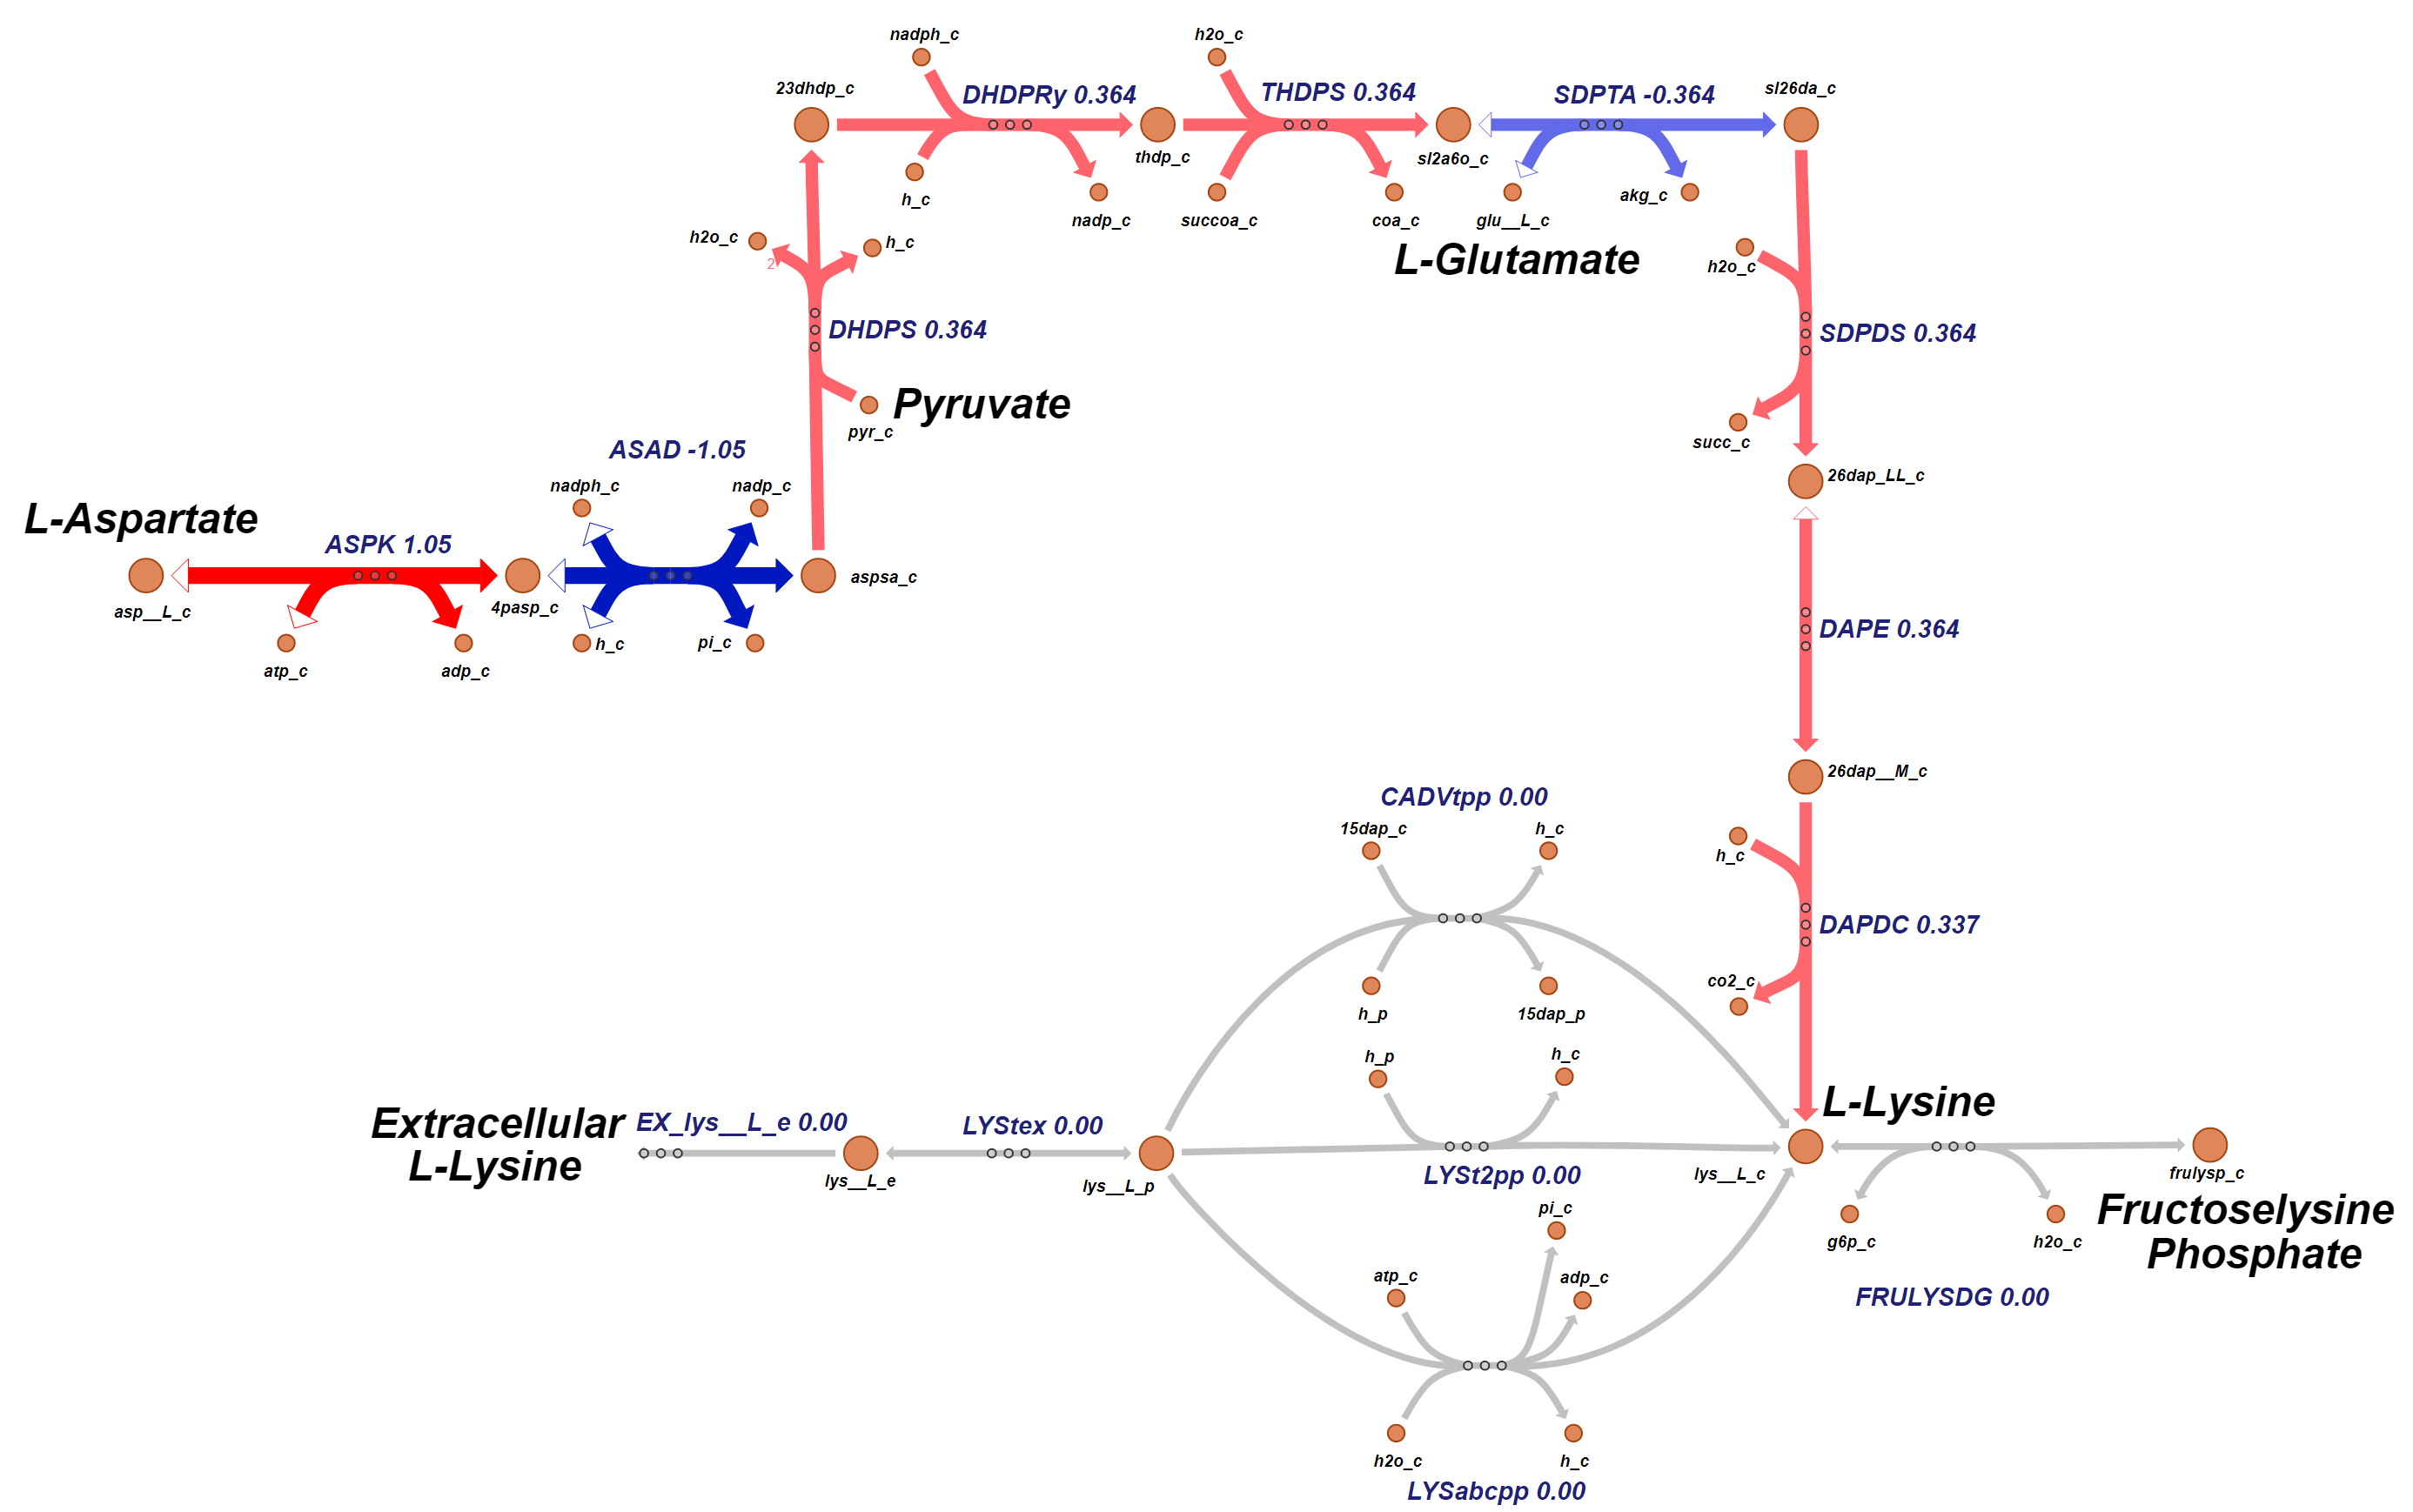

**Figure 8.** L-Lysine production under aerobic conditions (Lysine_Biosynthesis_Aerobic.png or Lysine_Biosynthesis_Aerobic.svg).

This figure illustrates that only the primary biosynthesis pathway is used in this simple aerobic case. Note that both reactions 'ASAD' and 'SDPTA' are reactions operating in reverse mode. For this figure red indicates the reaction is operating in the forward mode of operation with the thicknes of the line associated with the amount of flux. The blue indicates the reaction is operating in the reverse mode of operation.

## 4.3 Excess L-Lysine Production

When a cell is producing a recombinant protein, it might be required to produce additional L-Lysine for the desired bioproduct.  What is the maximum amount of excess L-Lysine, beyond what the cell needs for normal growth, that can be produced for a given growth-rate?

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'EX_o2_e',-30,'l'); % Set oxygen uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction

ASPK	1.05	
ASAD	-1.05	
DHDPS	0.364	
DHDPRy	0.364	
THDPS	0.364	
SDPTA	-0.364	
SDPDS	0.364	
DAPE	0.364	
DAPDC	0.337	
CADVtpp	0	
LYSt2pp	0	
LYSabcpp	0	
EX_lys__L_e	0	
LYStex	0	
FRULYSDG	0	


model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
FBAsolution = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',FBAsolution.f,'b'); % Set fixed growth-rate
model = addDemandReaction(model, 'lys__L_c');
[tmp,Threonine_MAX_rxnID] = ismember({'DM_lys__L_c'},model.rxns);
model = changeObjective(model,'DM_lys__L_c'); % Set the objective function
FBAsolution_Lysine = optimizeCbModel(model,'max'); % Perform FBA to find optimal growth-rate
xMin = 0.5;
xMax = FBAsolution.f;
xInc = (xMax - xMin)/20;
x = xMin;
excessLysine = [];
growthRate = [];
for i = 1:21

DM_lys__L_c	lys__L_c 	->	


    model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',x,'b'); % Set fixed growth-rate  
    FBAsolution_Lysine = optimizeCbModel(model,'max'); % Perform FBA
    excessLysine(i) = FBAsolution_Lysine.f;
    growthRate(i) = x;
    x = x + xInc;
end
plot(growthRate,excessLysine)
title('Excess L-Lysine'); 
xlabel('Growth-rate (h-1)'); ylabel('Excess L-Lysine (mmol.gDW-1.h-1)');

**Figure 9. **A plot showing the maximum amount of L-Lysine that can be produced for a given growth-rate.

This figure illustrates that as the need for excess L-Lysine increases the growth-rate will need to decrease. In this figure we can see that the excess L-Lysine flux can increase from 0.03343 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when the cell is at maximum growth-rate to 3.915 $\text{mmol}\cdot {\text{gDW}}^{-1} \cdot {\text{hr}}^{-1}$ when it is at 50% of that optimal growth-rate. Finally, to increase the L-Lysine flux beyond these levels will require using the pathways that allow for the transport of L-Lysine from the extracellular media. 

## 5. Aerobic vs Anaerobic Amino Acid Production

Now let's look at the total amount of flux that is created for each of these amino acids as the oxygen content varies from anerobic to aerobic.

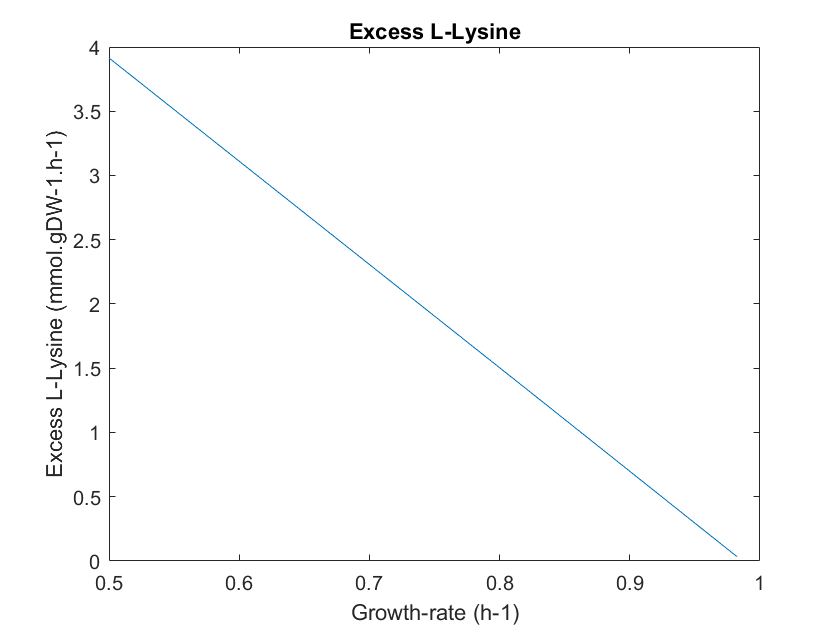

model = saved_model;
model = changeRxnBounds(model,'EX_glc__D_e',-10,'l'); % Set maximum glucose uptake
model = changeRxnBounds(model,'BIOMASS_Ec_iJO1366_WT_53p95M',-0,'b'); % Disable WT biomass reaction
model = changeObjective(model,'BIOMASS_Ec_iJO1366_core_53p95M'); % Set the objective function
thr_flux = [];
lys_flux = [];
for k = 1:31
    model = changeRxnBounds(model,'EX_o2_e',-(k-1),'b'); % Set oxygen uptake
    FBAsolution = optimizeCbModel(model,'max',0,0); % Perform FBA
    [P, C, vP, vC] = computeFluxSplits(model, {'ala__L_c'}, FBAsolution.x);

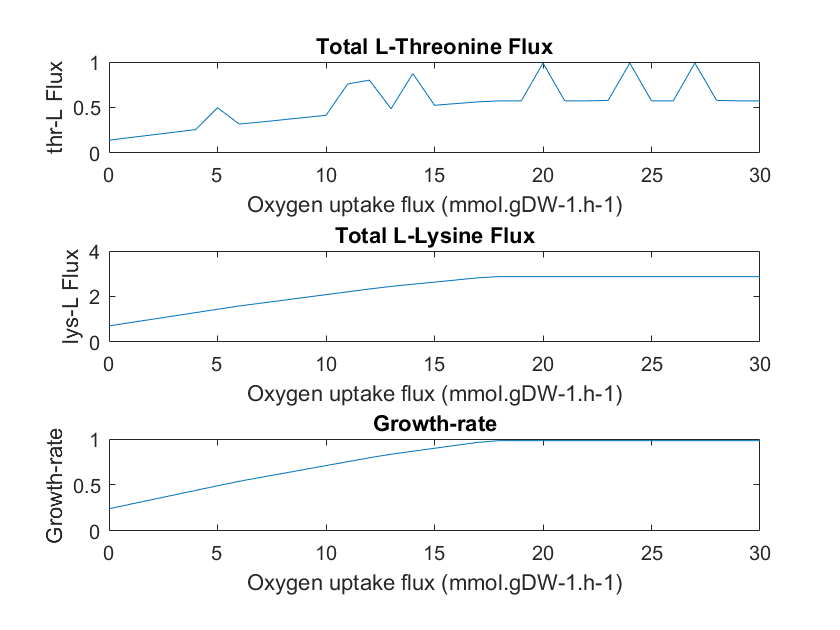

    thr_flux(k) = sum(vP);
    [P, C, vP, vC] = computeFluxSplits(model, {'asp__L_c'}, FBAsolution.x);
    lys_flux(k) = sum(vP);    
    growthRate(k) = FBAsolution.f;
end

figure(1)
oFlux = 0:30;
ax1 = subplot(3,1,1); % top subplot
ax2 = subplot(3,1,2); % middle subplot
ax3 = subplot(3,1,3); % bottom subplot

plot(ax1,oFlux,thr_flux)
title(ax1,'Total L-Threonine Flux'); 
xlabel(ax1,'Oxygen uptake flux (mmol.gDW-1.h-1)'); ylabel(ax1,'thr-L Flux');

plot(ax2,oFlux,asp_flux);
title(ax2,'Total L-Lysine Flux'); 
xlabel(ax2,'Oxygen uptake flux (mmol.gDW-1.h-1)'); ylabel(ax2,'lys-L Flux'); 

plot(ax3,oFlux,growthRate);
title(ax3,'Growth-rate'); 
xlabel(ax3,'Oxygen uptake flux (mmol.gDW-1.h-1)'); ylabel(ax3,'Growth-rate'); 

**Figure 10.** A plot showing the total amount of flux that is can be created for each of these amino acids as the oxygen content varies from anerobic to aerobic. Note that the noise on the L-Threonine chart is the result of loops in the production pathways. 

## 5. Conclusion

The purpose of this tutorial was to identify and review the structure and capabilities of the "Threonine and Lysine Metabolism" subsystem of the *E.coli* iJO1366 model. It began with an overview of the complete subsystem. This was followed by more detailed descritpions of the individaul L-Threonine and L-Lysine biosynthesis pathways. It concluded with a simulation showing the maximum flux that each these amino acids can produce in a range from anaerobic to aerobic conditions.

## References

- Palsson, B. (2015). Systems biology : constraint-based reconstruction and analysis. Cambridge, United Kingdom, Cambridge University Press.

- Palsson, B. (2006). Systems biology : properties of reconstructed networks. Cambridge ; New York, Cambridge University Press.

- Zachary A. King, Andreas Dräger, Ali Ebrahim, Nikolaus Sonnenschein, Nathan E. Lewis, and Bernhard O. Palsson (2015) *Escher: A web application for building, sharing, and embedding data-rich visualizations of biological pathways*, PLOS Computational Biology 11(8):

- M. Schaechter et al, "Microbe", ASM Press, 2006, p.119.

- D. White, "The physiology and biochemistry of prokaryotes," 3rd edition, Oxford University Press, 2007.